# Measure depths below cages

This guide explains how to measure the water depth below the farm cages

## About

This inquiry can be useful if NewDepomod fails to run. In some cases this is due to cages being too deep for the local bathymetry. This causes particles to be instantiated *within the seabed* and causes the model to throw an exception.

This process obviously requires information on the farm cages.

## Initialise original bathymetry data

We start with an original bathymetry representation

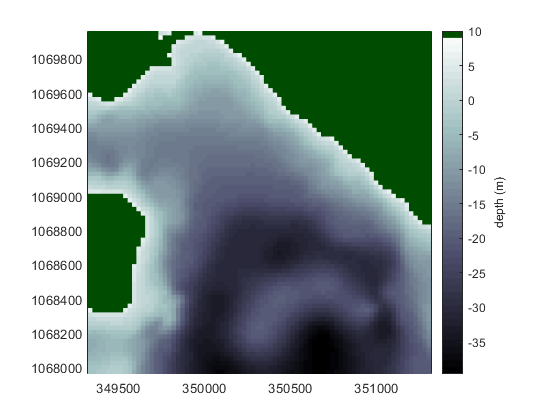

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = Depomod.Project.create(projectDir);
bathy      = project.bathymetry;

bathy.plot

## Initialise cage information

We need a representation of the farm cages. Each model run should have one, so we'll jsut grab the first solids run (actually the only one in this project)

cages = project.solidsRuns.first.cages

cages =   2 Site array with properties:

    cageGroups: {[4 Depomod.Layout.Cage.Group]  [4 Depomod.Layout.Cage.Group]}
          path: 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml'

Now, we'll get a list of the domain cell indexes that are situated under the cages.

underCageIndxs = bathy.underCageIndexes(cages)

underCageIndxs = 79×79 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

This is a boolean matrix represent a true or false for every domain grid cell. We can discover a few simple things about these cells.

find(underCageIndxs)

ans =         2801
        2802
        2803
        2880
        2881
        2882
        2958
        2959
        2960
        2961


These are the indexes that are situated below the cages. There appear to be 29 of them. Lets access the water depths for these cells.

underCageDepths = bathy.data(underCageIndxs)

underCageDepths =              -19.691168711
             -19.943747578
             -20.310381574
             -19.701221078
             -20.005867164
             -20.452662184
             -19.284236469
             -19.660714387
             -20.003245388
             -20.494326893


And what is the shallowest value?

max(underCageDepths) % max because water depth is negative

ans =              -17.289184254

The water depths under the cages are over 17 m. This should be okay for our cages but let's just check.

cages.cageGroups{1}.cages{1}.height

ans =     12

Yes, the cages are only 12 m.